% Created by: Anthony H. Le
% Last updated: 2022-02-14

% BME 6250 - Biomechanics II
% Homework 2
% Due date: 2022-02-15, 09:00 MST

## Problem 2a

close all; clear;

syms m k I1 I2 I3 Id C
% m: mu
% k: kappa
% I1: invariant 1
% I2: invariant 2
% I3: invariant 3
% Id: identity tensor

% Id = diag([1 1 1])

% modified St. Vanant-Kirchhoff strain energy function
W = (m/2) * (I1 - 3)^2 + (k/2) * (log(I3))^2

$$W = \frac{m\,{\left(I_{1}-3\right)}^{2}}{2}+\frac{k\,{\log\left(I_{3}\right)}^{2}}{2}$$

% derivatives of the strain energy function w.r.t. each invariant
dW1 = diff(W, I1)

$$dW1 = \frac{m\,\left(2\,I_{1}-6\right)}{2}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = \frac{k\,\log\left(I_{3}\right)}{I_{3}}$$

% I1 = eval(trace(C))
% I2 = eval((1/2) * ((trace(C))^2 - trace(C^2)))
% I3 = eval(det(C))
% dI1 = Id
% dI2 = I1 * Id - C
% dI3 = I3 \ C
% S = subs(2 * (dW1 * dI1 + dW2 * dI2 + dW3 * dI3))

% sub for the 2nd P-K stress for an isotropic hyperelastic material
S = 2 * ((dW1 + I1 * dW2 + I2 * dW3) * Id - (dW2 + I1 * dW3) * C + dW3 * C^2)

$$S = 2\,\mathrm{Id}\,\left(\frac{m\,\left(2\,I_{1}-6\right)}{2}+\frac{I_{2}\,k\,\log\left(I_{3}\right)}{I_{3}}\right)+\frac{2\,C^{2}\,k\,\log\left(I_{3}\right)}{I_{3}}-\frac{2\,C\,I_{1}\,k\,\log\left(I_{3}\right)}{I_{3}}$$

## Problem 2b

close all; clear;

syms m k I1 I2 I3 Id
% m: mu
% k: kappa
% I1: invariant 1
% I2: invariant 2
% I3: invariant 3
% Id: identity tensor

% define identity tensor
Id = diag([1 1 1])

Id =      1     0     0
     0     1     0
     0     0     1



% deformation gradient
F = Id

F =      1     0     0
     0     1     0
     0     0     1



C = transpose(F) * F

C =      1     0     0
     0     1     0
     0     0     1



% modified St. Vanant-Kirchhoff strain energy
W = (m/2) * (I1 - 3)^2 + (k/2) * (log(I3))^2

$$W = \frac{m\,{\left(I_{1}-3\right)}^{2}}{2}+\frac{k\,{\log\left(I_{3}\right)}^{2}}{2}$$


% derivatives of the strain energy function w.r.t. each invariant
dW1 = diff(W, I1)

$$dW1 = \frac{m\,\left(2\,I_{1}-6\right)}{2}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = \frac{k\,\log\left(I_{3}\right)}{I_{3}}$$


% define invariants
I1 = trace(C)

I1 = 3

I2 = (1/2) * ((trace(C))^2 - trace(C^2))

I2 = 3

I3 = det(C)

I3 = 1

% dI1 = Id
% dI2 = I1 * Id - C
% dI3 = I3 \ C
% S = subs(2 * dW1 * dI1 + dW2 * dI2 + dW3 * dI3)
% sub for the 2nd P-K stress for an isotropic hyperelastic material
S = subs(2 * ((dW1 + I1 * dW2 + I2 * dW3) * Id - (dW2 + I1 * dW3) * C + dW3 * C^2))

$$S = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Problem 3

close all; clear; clc;

syms m Jm I1 I2 I3 Id lambda
% m: mu
% Jm: dimensionless parameter
% I1: invariant 1
% I2: invariant 2
% I3: invariant 3
% Id: identity tensor
% lambda: stretch ratio

% Gent incompressible isotropic hyperelastic model
W = -(m/2) * Jm * log(1 - ((I1 - 3) / Jm))

$$W = -\frac{\mathrm{Jm}\,m\,\log\left(1-\frac{I_{1}-3}{\mathrm{Jm}}\right)}{2}$$


% derivatives w.r.t. each invariant
dW1 = diff(W, I1)

$$dW1 = -\frac{m}{2\,\left(\frac{I_{1}-3}{\mathrm{Jm}}-1\right)}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = 0$$


% deformation gradient
F = diag([lambda lambda 1/(lambda^2)])

$$F = \left(\begin{array}{ccc} \lambda & 0 & 0\\ 0 & \lambda & 0\\ 0 & 0 & \frac{1}{\lambda^{2}} \end{array}\right)$$


B = F * transpose(F)

$$B = \left(\begin{array}{ccc} \lambda^{2} & 0 & 0\\ 0 & \lambda^{2} & 0\\ 0 & 0 & \frac{1}{\lambda^{4}} \end{array}\right)$$

Binv = inv(transpose(F)) * inv(F)

$$Binv = \left(\begin{array}{ccc} \frac{1}{\lambda^{2}} & 0 & 0\\ 0 & \frac{1}{\lambda^{2}} & 0\\ 0 & 0 & \lambda^{4} \end{array}\right)$$


% Jacobian 
J = det(F)

$$J = 1$$

% Id = diag([1 1 1])

% solve for Cauchy stress
T = (2/J) * (dW1 * B - I3 * dW2 * Binv + (I2 * dW2 + I3 * dW3) * Id)

$$T = \left(\begin{array}{ccc} -\frac{\lambda^{2}\,m}{\frac{I_{1}-3}{\mathrm{Jm}}-1} & 0 & 0\\ 0 & -\frac{\lambda^{2}\,m}{\frac{I_{1}-3}{\mathrm{Jm}}-1} & 0\\ 0 & 0 & -\frac{m}{\lambda^{4}\,\left(\frac{I_{1}-3}{\mathrm{Jm}}-1\right)} \end{array}\right)$$


% solve for 1st P-K stress
P = J * T * transpose(inv(F))

$$P = \left(\begin{array}{ccc} -\frac{\lambda \,m}{\frac{I_{1}-3}{\mathrm{Jm}}-1} & 0 & 0\\ 0 & -\frac{\lambda \,m}{\frac{I_{1}-3}{\mathrm{Jm}}-1} & 0\\ 0 & 0 & -\frac{m}{\lambda^{2}\,\left(\frac{I_{1}-3}{\mathrm{Jm}}-1\right)} \end{array}\right)$$


% solve for 2nd P-K stress
S = F \ P

$$S = \left(\begin{array}{ccc} \frac{\mathrm{Jm}\,m}{\mathrm{Jm}-I_{1}+3} & 0 & 0\\ 0 & \frac{\mathrm{Jm}\,m}{\mathrm{Jm}-I_{1}+3} & 0\\ 0 & 0 & \frac{\mathrm{Jm}\,m}{\mathrm{Jm}-I_{1}+3} \end{array}\right)$$

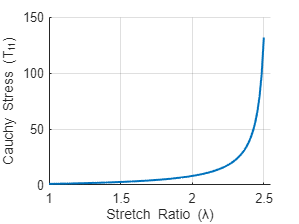


% stretch ratio from 1 to 2.5
lambda = linspace(1, 2.5);
m = 1.0;
Jm = 10.0;

% define invariant, I1
I1 = eval(trace(B));

% calculate 11 component of Cauchy stress
T11 = subs(T(1, 1));

% plot the 11 component of the Cauchy stress vs stretch ratio
figure();
hold on;
plot(lambda, T11, "LineWidth", 1.5);
xlabel('Stretch Ratio (\lambda)');
ylabel('Cauchy Stress (T_{11})')
xlim([1 2.55]);
grid on;
hold off;

## Problem 4

close all; clear; clc;

% establish symbolic variables based on problem setup
syms h h0 r r0 I1 I2 I3 Id lambda C1 C2 Cnh

% define the identity tensor
Id = diag([1 1 1]);

% Mooney-Rivlin constitutive relation
Wmr = C1 * (I1 - 3) + C2 * (I2 - 3)

$$Wmr = C_{1}\,\left(I_{1}-3\right)+C_{2}\,\left(I_{2}-3\right)$$


% Neo-Hookean constittuive relation
Wnh = Cnh * (I1 - 3)

$$Wnh = \mathrm{Cnh}\,\left(I_{1}-3\right)$$


% deformation gradient
F = diag([lambda lambda 1/(lambda^2)])

$$F = \left(\begin{array}{ccc} \lambda & 0 & 0\\ 0 & \lambda & 0\\ 0 & 0 & \frac{1}{\lambda^{2}} \end{array}\right)$$

B = F * transpose(F)

$$B = \left(\begin{array}{ccc} \lambda^{2} & 0 & 0\\ 0 & \lambda^{2} & 0\\ 0 & 0 & \frac{1}{\lambda^{4}} \end{array}\right)$$

Binv = inv(transpose(F)) * inv(F)

$$Binv = \left(\begin{array}{ccc} \frac{1}{\lambda^{2}} & 0 & 0\\ 0 & \frac{1}{\lambda^{2}} & 0\\ 0 & 0 & \lambda^{4} \end{array}\right)$$

## (a)

% derivative of strain energy functions w.r.t. each invariant
% Mooney-Rivlin
dWmr1 = diff(Wmr, I1)

$$dWmr1 = C_{1}$$

dWmr2 = diff(Wmr, I2)

$$dWmr2 = C_{2}$$

dWmr3 = diff(Wmr, I3)

$$dWmr3 = 0$$


% Neo-Hookean
dWnh1 = diff(Wnh, I1)

$$dWnh1 = \mathrm{Cnh}$$

dWnh2 = diff(Wnh, I2)

$$dWnh2 = 0$$

dWnh3 = diff(Wnh, I3)

$$dWnh3 = 0$$


% define invariant
I1 = eval(trace(B))

$$I1 = 2\,\lambda^{2}+\frac{1}{\lambda^{4}}$$

I2 = eval((1/2) * (trace(B)^2 - trace(B^2)))

$$I2 = \frac{{\left(2\,\lambda^{2}+\frac{1}{\lambda^{4}}\right)}^{2}}{2}-\lambda^{4}-\frac{1}{2\,\lambda^{8}}$$

I3 = eval(det(B))

I3 = 1


% define Jacobian
J = eval(det(F))

J = 1


% solve for Cauchy stress using isotropic incompressible strain energy
% then solve for pressure using 33 component of Cauchy stress
% and add to Cauchy stress
% Mooney-Rivlin
Tmr = (2/J) * (dWmr1 * B - I3 * dWmr2 * Binv + (I2 * dWmr2 + I3 * dWmr3) * Id)

$$Tmr = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & 0 & 0\\ 0 & \sigma_{1} & 0\\ 0 & 0 & \frac{2\,C_{1}}{\lambda^{4}}-\sigma_{2}-2\,C_{2}\,\lambda^{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,C_{1}\,\lambda^{2}-\sigma_{2}-\frac{2\,C_{2}}{\lambda^{2}}\\ \sigma_{2}=2\,C_{2}\,\left(\lambda^{4}-\frac{{\left(2\,\lambda^{2}+\frac{1}{\lambda^{4}}\right)}^{2}}{2}+\frac{1}{2\,\lambda^{8}}\right) \end{array}$$

Tmr33 = Tmr(3, 3);
Tmr = Tmr - Tmr33 * eye(3, 3)

$$Tmr = \left(\begin{array}{ccc} 2\,C_{1}\,\lambda^{2}-\frac{2\,C_{2}}{\lambda^{2}}-\frac{2\,C_{1}}{\lambda^{4}}+2\,C_{2}\,\lambda^{4} & 0 & 0\\ 0 & 2\,C_{1}\,\lambda^{2}-\frac{2\,C_{2}}{\lambda^{2}}-\frac{2\,C_{1}}{\lambda^{4}}+2\,C_{2}\,\lambda^{4} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Tmr11 = simplify(Tmr(1, 1))

$$Tmr11 = \frac{2\,\left(C_{2}\,\lambda^{2}+C_{1}\right)\,\left(\lambda^{6}-1\right)}{\lambda^{4}}$$


% Neo-Hookean
Tnh = (2/J) * (dWnh1 * B - I3 * dWnh2 * Binv + (I2 * dWnh2 + I3 * dWnh3) * Id)

$$Tnh = \left(\begin{array}{ccc} 2\,\mathrm{Cnh}\,\lambda^{2} & 0 & 0\\ 0 & 2\,\mathrm{Cnh}\,\lambda^{2} & 0\\ 0 & 0 & \frac{2\,\mathrm{Cnh}}{\lambda^{4}} \end{array}\right)$$

Tnh33 = Tnh(3, 3);
Tnh = Tnh - Tnh33 * eye(3, 3)

$$Tnh = \left(\begin{array}{ccc} 2\,\mathrm{Cnh}\,\lambda^{2}-\frac{2\,\mathrm{Cnh}}{\lambda^{4}} & 0 & 0\\ 0 & 2\,\mathrm{Cnh}\,\lambda^{2}-\frac{2\,\mathrm{Cnh}}{\lambda^{4}} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Tnh11 = simplify(Tnh(1, 1))

$$Tnh11 = \frac{2\,\mathrm{Cnh}\,\left(\lambda^{6}-1\right)}{\lambda^{4}}$$

## (b)

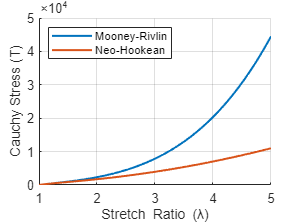

% stretch ratio from 1 to 5
lambda = linspace(1, 5);

% define constants
C1 = 185; % kPa
C2 = 28.2; % kPa
Cnh = 220; % kPa
% Id = diag([1 1 1]);

% sub to calculate Cauchy stress
Tmr11 = subs(Tmr(1, 1));
Tnh11 = subs(Tnh(1, 1));

% plot Cauchy stress for stretch ration from 1 to 5
figure();
hold on;
plot(lambda, Tmr11, 'LineWidth', 1.5);
plot(lambda, Tnh11, 'LineWidth', 1.5);
xlabel('Stretch Ratio (\lambda)');
ylabel('Cauchy Stress (T)')
legend('Mooney-Rivlin', 'Neo-Hookean', 'Location', 'northwest');
grid on;
hold off;

## (c)

% re-establish lambda as symbolic variable
syms lambda

% solve for internal pressure by subbing in the 
% rewritten Laplace's equation
% pmr = (2 * h * Tmr(1, 1)) / r
pmr = (2 * Tmr(1, 1) * h0) / ((lambda^3) * r0)

$$pmr = \frac{h_{0}\,\left(4\,C_{1}\,\lambda^{2}-\frac{4\,C_{2}}{\lambda^{2}}-\frac{4\,C_{1}}{\lambda^{4}}+4\,C_{2}\,\lambda^{4}\right)}{\lambda^{3}\,r_{0}}$$

% pnh = (2 * h * Tnh(1, 1)) / r
pnh = (2 * Tnh(1, 1) * h0) / ((lambda^3) * r0)

$$pnh = \frac{h_{0}\,\left(4\,\mathrm{Cnh}\,\lambda^{2}-\frac{4\,\mathrm{Cnh}}{\lambda^{4}}\right)}{\lambda^{3}\,r_{0}}$$

## (d)

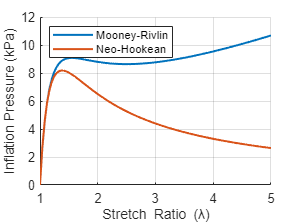

% stretch ratio from 1 to 5
lambda = linspace(1, 5);

% define initial values for thickness and inner radius
h0 = 1.5; % mm
r0 = 100; % mm
r = r0 .* lambda;
h = h0 ./ (lambda.^2);

% sub to calculate internal pressures
pmr11 = subs(pmr);
pnh11 = subs(pnh);

% plot inflation pressure for stretch ratio from 1 to 5
figure();
hold on;
plot(lambda, pmr11, 'LineWidth', 1.5);
plot(lambda, pnh11, 'LineWidth', 1.5);
xlabel('Stretch Ratio (\lambda)');
ylabel('Inflation Pressure (kPa)');
legend('Mooney-Rivlin', 'Neo-Hookean', 'Location', 'northwest');
grid on;
hold off;